# Taratura manuale dell'anello di posizione

Obiettivo: tarare manualmente il controllore di posizione esterno mantenendo il loop esterno puramente proporzionale.

Il modello viene caricato come nel livescript attuale di taratura velocita.

**Parametri da settare: **

- Parametri e filtro notch devono essere coerenti con quanto deciso nello script *taratura_manuale_velocita.mlx*

- *wc ***deve **essere la frequenza di taglio di P_pos (Guarda da Bode)

- *alpha*, ovvero di quante decadi andare indietro

clear all;close all;clc;
load ../data/models/000/model_joint3.mat
Ts=1e-3;
s=tf('s');
sys_vel_motore=tf(modello_continuo);

Definisco il controllore di velocita come PI.

Inserire al posto di Kp_vel e Ti_vel i valori del controllore interno.


$$C_{vel}(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)$$


% Parametri
Kp_vel=47.58;      
Ti_vel=0.4;
% Controllore
C_vel=Kp_vel*(1+1/(Ti_vel*s));

Filtro notch (se utilizzato) per la taratura del loop interno di velocita.

use_notch=true;
wn=800;      % frequenza notch (da aggiornare per il joint corrente)
xci_z=0.2;   % smorzamento zeri
xci_p=0.8;   % smorzamento poli
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);

Processo in anello aperto visto dal controllore esterno

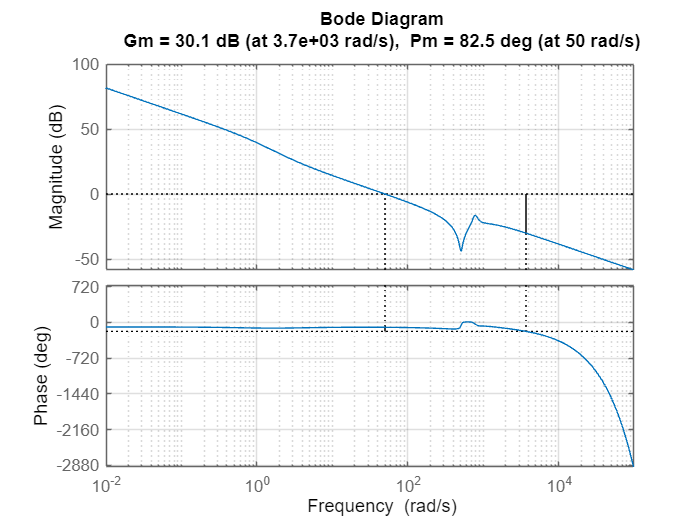

if use_notch
    P_vel=minreal(sys_vel_motore*notch);
else
    P_vel=sys_vel_motore;
end

figure
margin(C_vel*P_vel)
grid on

Il processo equivalente visto dal controllore di posizione e dato dal loop velocità chiuso:


$$F_{\text{vel}} = \frac{C_{\text{vel}} \, P_{\text{vel}}}{1 + C_{\text{vel}} \, P_{\text{vel}}}$$


e dall'integratore cinematico:


$$P_{\text{pos}} = F_{\text{vel}} \cdot \frac{1}{s}$$


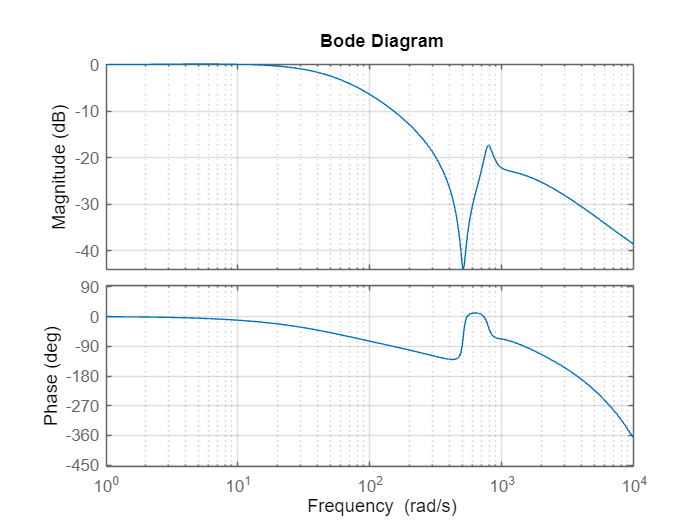

F_vel=feedback(C_vel*P_vel,1); % Chiudo il loop interno
P_pos=minreal(F_vel*(1/s)); % Aggiunta dell'integratore per ottenere la posizione

figure
bode(F_vel)
grid on

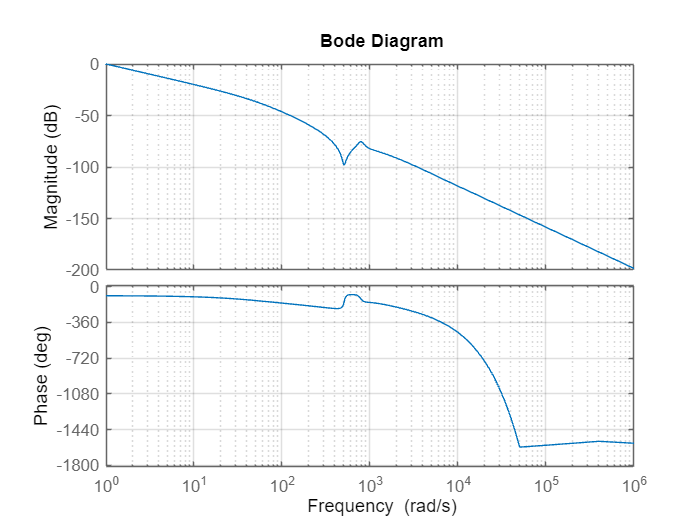


figure
bode(P_pos)
grid on

Taratura manuale dell'anello esterno di posizione con controllore P.


$$K_{p,\text{pos}} = \frac{1}{\left| P_{\text{pos}}\!\left(j \omega_{c,\text{pos}}\right) \right|}$$


wc_vel=1.04;     % usare la wc di P_pos
alpha=10;     % separazione di banda fissata
wc_pos=wc_vel/alpha;

Kp_pos=1/abs(squeeze(freqresp(P_pos,wc_pos)));
C_pos=Kp_pos

C_pos = 0.1040

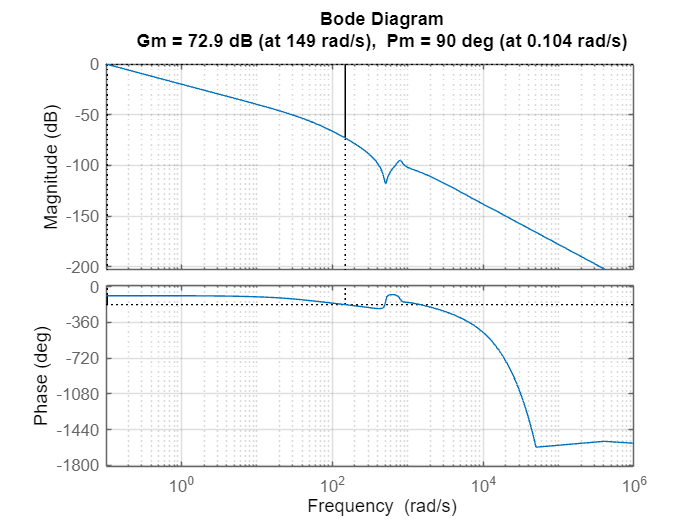

figure
margin(C_pos*P_pos)
grid on

Verifica del loop chiuso in posizione.

T_pos=feedback(C_pos*P_pos,1);

disp(['wc_pos [rad/s] = ',num2str(wc_pos)])

wc_pos [rad/s] = 0.104


disp(['Kp_pos = ',num2str(Kp_pos)])

Kp_pos = 0.10399


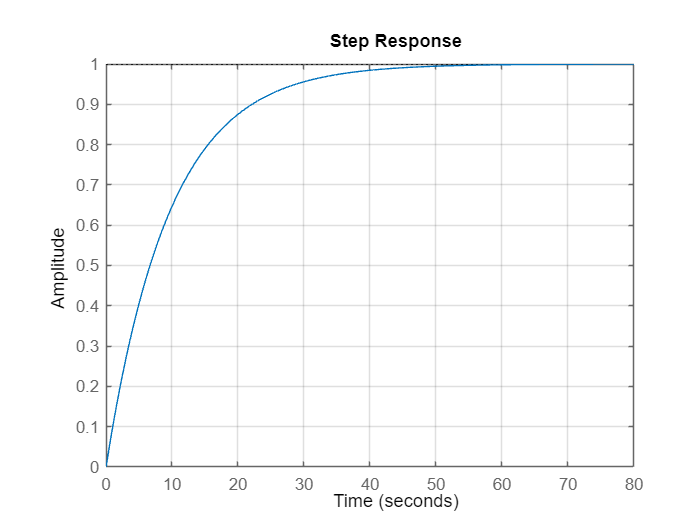

figure
step(T_pos)
grid on